# Satellite Image Processing - YCbCr 

*Author: Avalon Royer*

*Student of Geography & Urban Planning at the Université Paris Cité.*

Satellite image processing plays an important role in land use observation and analysis as it allows for the coverage of vast areas, monitoring changes over time, and distinguishing different types of surfaces through multi-spectral data. It is particularly used for visualizing land use in hard-to-reach areas more easily, but also to support decision-making in urban planning, agriculture, and natural resource management, and to detect environmental changes such as deforestation or urbanization more quickly since it provides the ability to compare the same area at different time periods.

## Importing and Reading the Image 

To read and display an image in MATLAB, we use the `imshow` function after assigning the title of the photo we want to analyze to a variable.

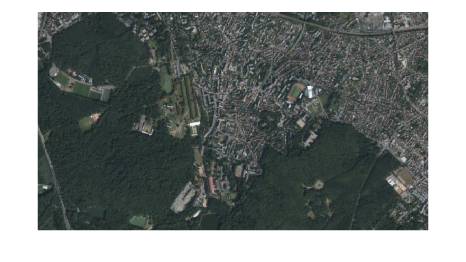

imageName="meudon_satellite.png";
RGB=imread(imageName);
imshow(imageName)

## Conversion from RGB to YCbCr 

The image is converted from the RGB color model to the YCbCr color model.

I = rgb2ycbcr(RGB);

## Definition of Thresholds 

The Y'CbCr color model is often used in digital video, digital photography, and image processing. It separates luminance (Y) and chrominance (Cb and Cr), which allows for more efficient image compression and better color management compared to the RGB model. The three components are luminance (Y), which represents color intensity, chrominance-blue (Cb), which is the difference between luminance and blue, and chrominance-red (Cr), which is the difference between luminance and red.

For example, if we want to represent the portion of the area covered by green vegetation, we will use the following max and min values:

yMin =40;
yMax =70;
cbMin =120;
cbMax =130;
crMin =100;
crMax =140;

## Conversion to Black & White Binary Mask 

With the following commands, we will isolate and visualize the parts of the image that fall within specific color ranges by creating a binary image mask based on these thresholds. We will obtain a binary mask (`sliderBW`) where the pixels within the specified ranges for the three color channels are set to true (1), and all other pixels are set to false (0). 

Next, we simply assign the created mask (`sliderBW`) to BW and then display the final image with `imshow`.

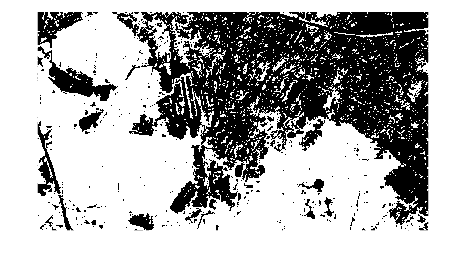

sliderBW = (I(:,:,1) >= yMin ) & (I(:,:,1) <= yMax) & ...
    (I(:,:,2) >= cbMin ) & (I(:,:,2) <= cbMax) & ...
    (I(:,:,3) >= crMin ) & (I(:,:,3) <= crMax);
BW = sliderBW;
imshow(BW)

## Final Segmentation 

We will isolate the black pixels to remove them from the image, segmenting it to leave only the part selected with the thresholds, in the RGB model.

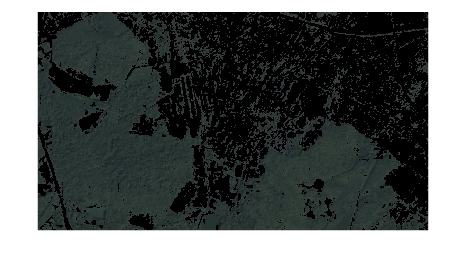

maskedRGBImage = RGB;
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
imshow(maskedRGBImage)

## Calculate the Percentage of Vegetation Relative to Urbanized Areas 

Next, we want to calculate the representative percentage of the green vegetation area relative to the entire image selected for analysis. The ratio `sum(sum(BW))/(nbrow*nbcol)` gives the proportion of the image occupied by white pixels, representing the vegetation (prctVege).

[nbrow,nbcol]=size(BW);
prctVege = sum(sum(BW))/(nbrow*nbcol)

prctVege = 0.5497

*Image: Google Maps*